# Lab 5: Edge Detection and Segmentation

close all; clear; clc;
I = im2double(rgb2gray(imread('peppers.png')));

## 1) Basic derivative filters (Sobel, Prewitt)

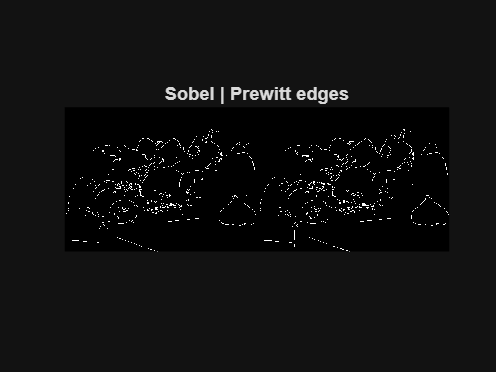

edges_sobel = edge(I,'Sobel');
edges_prewitt = edge(I,'Prewitt');
figure; montage({edges_sobel, edges_prewitt},'Size',[1 2]);
title('Sobel | Prewitt edges');

## 2) Canny detector (multi-stage)

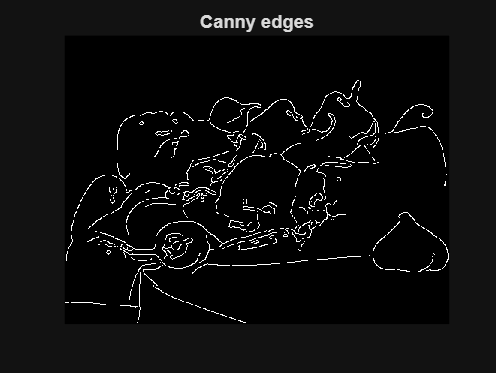

edges_canny = edge(I,'Canny',[0.05 0.2]);
figure; imshow(edges_canny); title('Canny edges');

## 3) Laplacian of Gaussian (LoG)

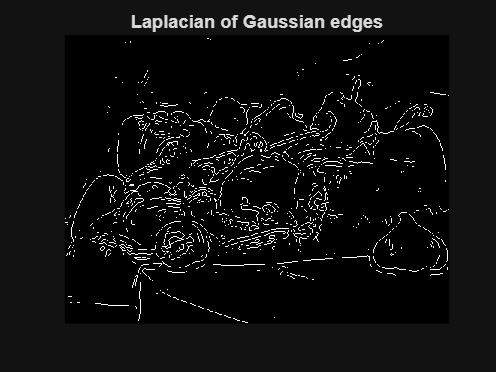

edges_log = edge(I,'log');
figure; imshow(edges_log); title('Laplacian of Gaussian edges');

## 4) Edge map → segmentation (Otsu threshold)

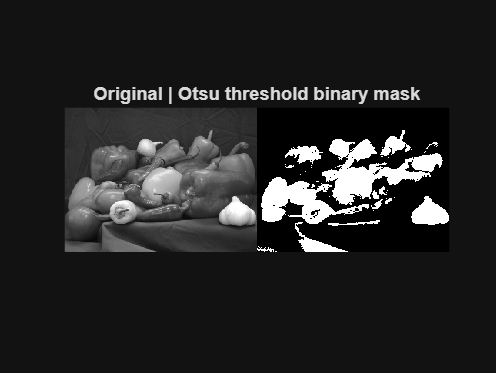

level = graythresh(I); % Otsu method
BW = imbinarize(I,level);
figure; montage({I,BW},'Size',[1 2]);
title('Original | Otsu threshold binary mask');

## 5) Label and visualize regions

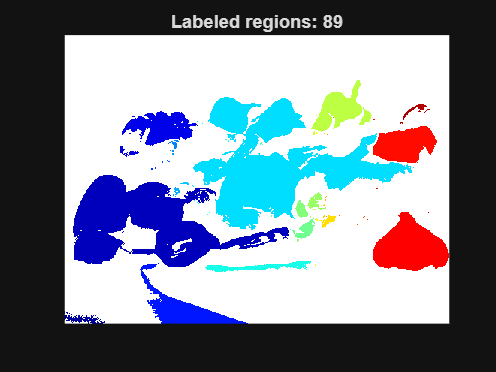

[L,num] = bwlabel(BW);
RGB = label2rgb(L);
figure; imshow(RGB); title(['Labeled regions: ',num2str(num)]);

## 6) Reflections

- Which operator gives the thinnest, cleanest edges? 

    Canny does.

- Why does Canny outperform simple gradient filters? 

    Canny usually outperforms simple gradient filters like Sobel or Prewitt because it does more than just measure local intensity change. It first smooths the image to reduce noise, then uses non-maximum suppression to make edges thin, and finally applies hysteresis thresholding to keep weak edge pixels only when they connect to strong ones.

- How does Otsu relate to histogram-based thresholding?

    It detects the brightness difference between objects and background by identifying the two local maxima in histogram, then uses a threshold to block one of the maxima considered as background. (I guess.)